## ESERCITAZIONE CONTROLLI AUTOMATICI 2023-2024

Si consideri il processo descritto dalla funzione di trasferimento:

$$$
P(s) = \frac{10(s-1)}{s^2+4s+8}
$$$,

e le seguenti specifiche a regime e nel transitorio:

- Errore a regime per ingressi a rampa inferiore al 10%

- Overshoot inferiore al 20%

### Sketch soluzione proposta:

clc 
clear all
close all
s = tf([1 0],1);
P = 10*(s-1)/(s^2+4*s+8);


Per soddisfare le speciche a regime 1), è possibile inserire un solo polo nel controllore sebbene il vincolo sull'errore a regime richiede un guadagno di anello che rende difficile la stabilizzazione. Si procede allora ad inserire un doppio polo nell'origine ed un guadagno negativo per stabilizzare il sistema, inserendo uno zero sufficientemente vicino il luogo per attirarne i rami e assicurare un range di guadagni per la stabilità asintotica a ciclo chiuso: attenzione si avranno di conseguenza poli dominanti del sistema a ciclo chiuso molto lenti, ma non ci sono specifiche di velocità di risposta del sistema retroazionato.

C1 = -0.235*(s+0.1)/s^2

C1 =
 
  -0.235 s - 0.0235
  -----------------
         s^2
 
Continuous-time transfer function.
Model Properties


L1 = C1*P

L1 =
 
  -2.35 s^2 + 2.115 s + 0.235
  ---------------------------
      s^4 + 4 s^3 + 8 s^2
 
Continuous-time transfer function.
Model Properties



figure(1)
margin(L1)

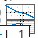

grid on
legend('L_1')

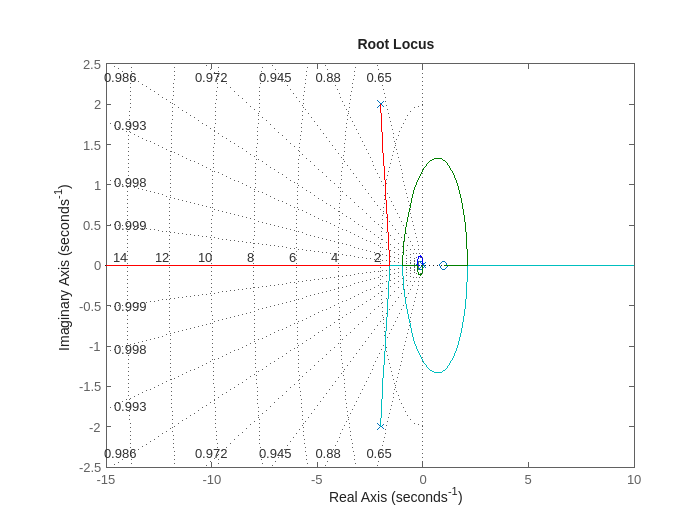


figure(2)
rlocus(L1)
grid on

Non avendo vincoli sul tempo di assestamento (banda passante del sistema a ciclo chiuso) inserisco  un filtro in ingresso al riferimento per soddisfare la specifica sulla sovraelongazione.

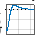

tau_fr = 3;
Fr = 1/(tau_fr*s+1);
Wyr = minreal(Fr*(C1*P)/(1+C1*P));
figure(1)
step(Wyr)
grid on

Introduciamo un disturbo d2 di 50 rad/sec per il quale vogliamo reiezione asintotica: considero quindi un filtro sul ramo di retroazione  H(s) con due zeri alla medesima pulsazione angolare con due poli sufficientemente veloci (diverse soluzioni possibili di dove introdurre tali zeri...).

H = ((s/(50*2*pi))^2+1)/(0.1*s+1)^2

H =
 
          s^2 + 9.87e04
  ------------------------------
  987 s^2 + 1.974e04 s + 9.87e04
 
Continuous-time transfer function.
Model Properties


L2 = C1*P*H

L2 =
 
     -2.35 s^4 + 2.115 s^3 - 2.319e05 s^2 + 2.087e05 s + 2.319e04
  -------------------------------------------------------------------
  987 s^6 + 2.369e04 s^5 + 1.855e05 s^4 + 5.527e05 s^3 + 7.896e05 s^2
 
Continuous-time transfer function.
Model Properties


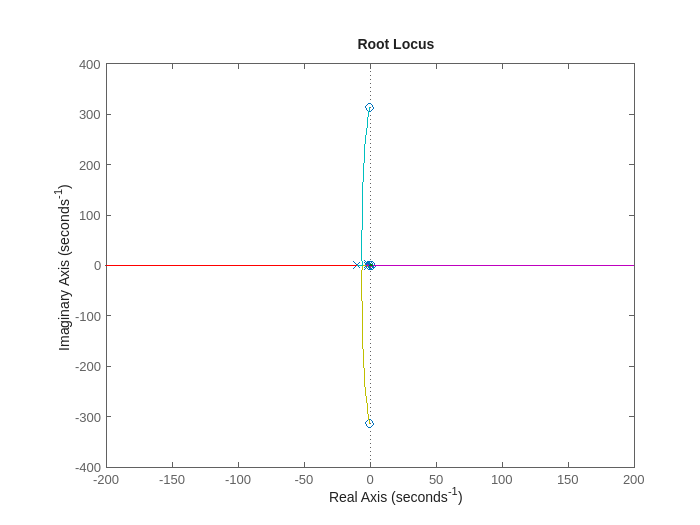


figure(1)
rlocus(L2)

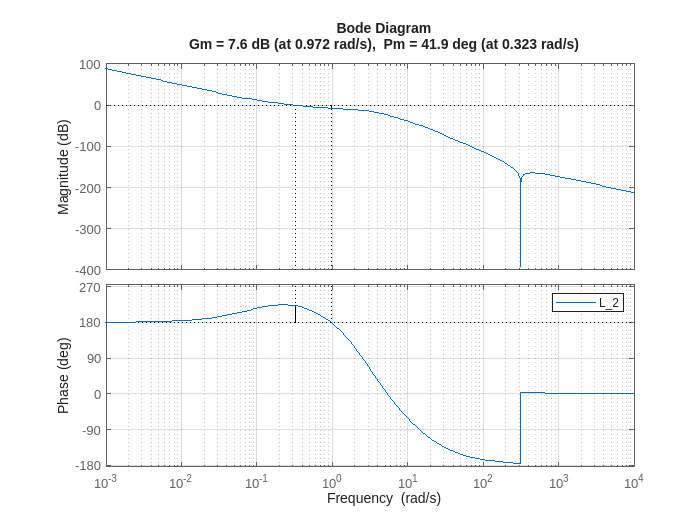


figure(2)
margin(L2)
grid on
legend('L_2')

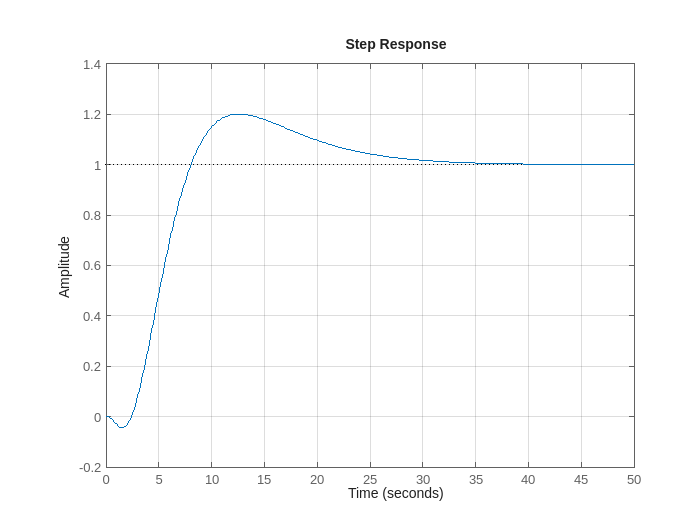



Wyr = minreal(Fr*(C1*P)/(1+C1*P*H));
figure(3)
step(Wyr)
grid on

Ora considero un ritardo di 50 ms.

P1 = P*exp(-0.05*s);
C2 = 1.3*C1; %posso aumentare di poco il guadagno per assicurare overshoot e tempo di assestamento migliore...rete anticipatrice?
L3 = C2*P1*H

L3 =
 
                    -3.055 s^4 + 2.749 s^3 - 3.015e05 s^2 + 2.714e05 s + 3.015e04
  exp(-0.05*s) * -------------------------------------------------------------------
                 987 s^6 + 2.369e04 s^5 + 1.855e05 s^4 + 5.527e05 s^3 + 7.896e05 s^2
 
Continuous-time transfer function.
Model Properties


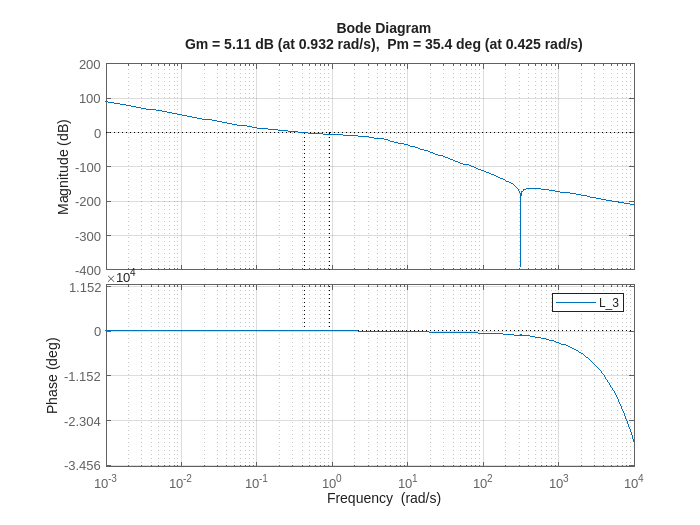

figure(2)
margin(L3) %DA FARE: dimostrare con Nyquist, il luogo delle radici non può essere usato con i ritardi
grid on
legend('L_3')



Wyr = minreal(Fr*(C2*P1)/(1+C2*P1*H));

1 state removed.


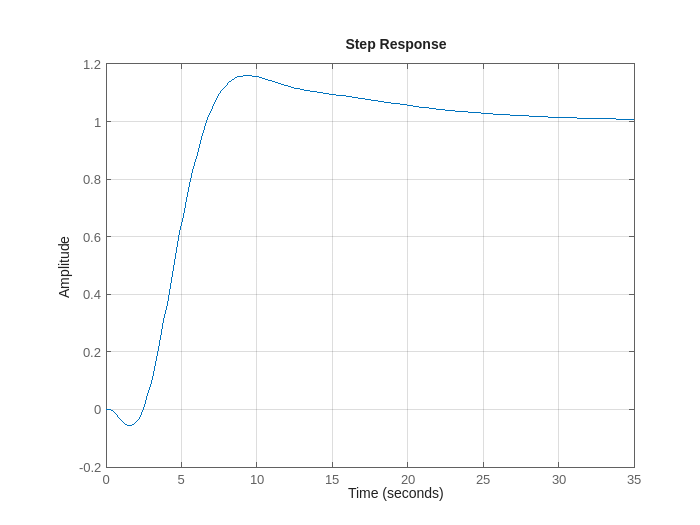

figure(3)
step(Wyr)
grid on

Ora immagino di dover discretizzare il controllore ed analizzo il sistema a tempo discreto

% Genero una versione discretizzata del controllore Cz: attenzione non è
% stato sintetizzato nel piano w equivalente di Tustin quindi la stabilità
% del sistema a ciclo chiuso a tempo discreto DEVE essere verificata e se
% necessario modificare il controllore

Ts = 0.05; %(uguale al ritardo così da avere sul modello della P1z un ritardo netto di un campione)
Cz = c2d(C2,Ts,'Tustin'); % con la discretizzazione usando il cambio di coordinate bilineare di Tustin
P1z = c2d(P1,Ts,'zoh'); %considero un organo di tenuta di ordine zero
Frz = c2d(Fr,Ts,'Tustin');
Hz = c2d(H,Ts,'Tustin');
Lz = Cz*P1z*Hz;
Wyz = minreal(minreal(Frz*(Cz*P1z)/(1+Cz*P1z*Hz)))

Wyz =
 
           -2.784e-05 z^11 + 0.0001405 z^10 - 0.0002374 z^9 + 4.203e-05 z^8 + 0.0003599 z^7 - 0.0004413 z^6 + 9.512e-05 z^5 + 0.0001945 z^4 - 0.0001812 z^3 + 6.429e-05 z^2 - 8.585e-06 z
  z^(-1) * ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
                        z^12 - 9.785 z^11 + 43.42 z^10 - 115.3 z^9 + 203.8 z^8 - 251.3 z^7 + 220.7 z^6 - 138 z^5 + 60.23 z^4 - 17.46 z^3 + 3.026 z^2 - 0.2378 z + 0.0001153
 
Sample time: 0.05 seconds
Discrete-time transfer function.


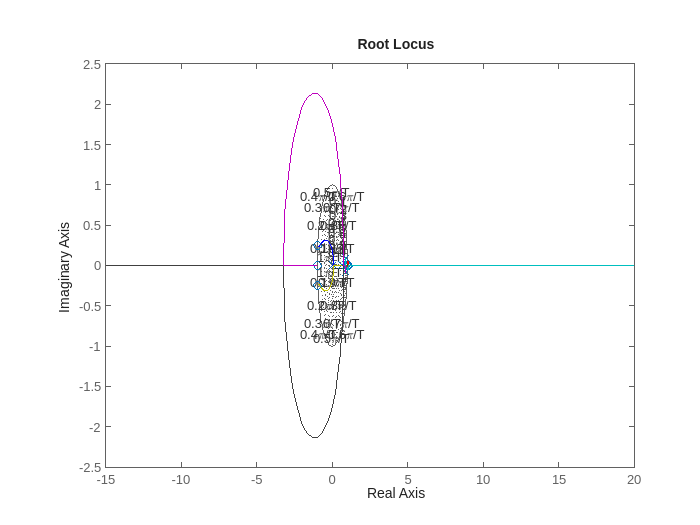


figure(1)
rlocus(Lz) %guardo i poli del sistema a ciclo chiuso segliendo guadagno unitario sul grafico
grid on

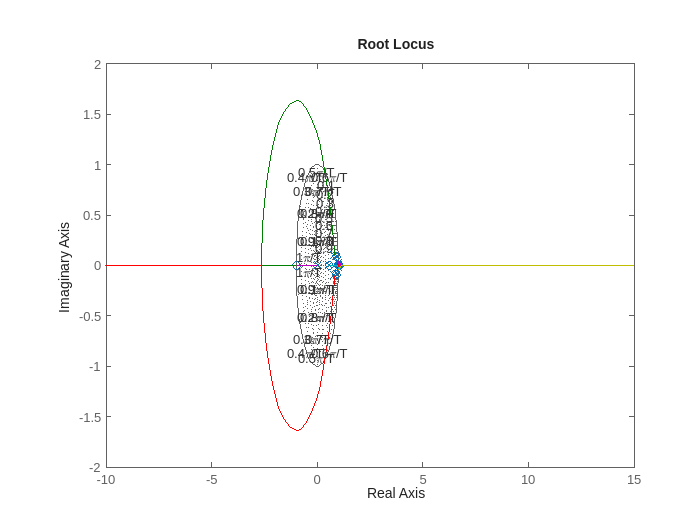


figure(2)
rlocus(Wyz) %guardo i poli del sistema a ciclo chiuso segliendo guadagno zero, ovvero dove sono le x nel grafico
grid on %E' necessario modificare il controllore (provare anche a ridurre Ts...)

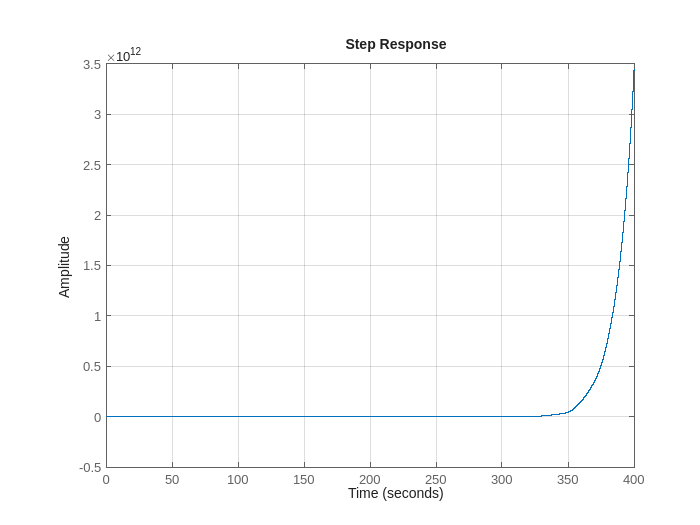


figure(2)
step(Wyz)
grid on